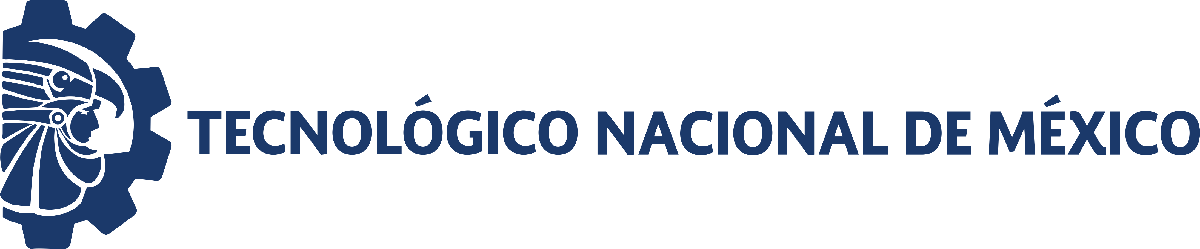                                 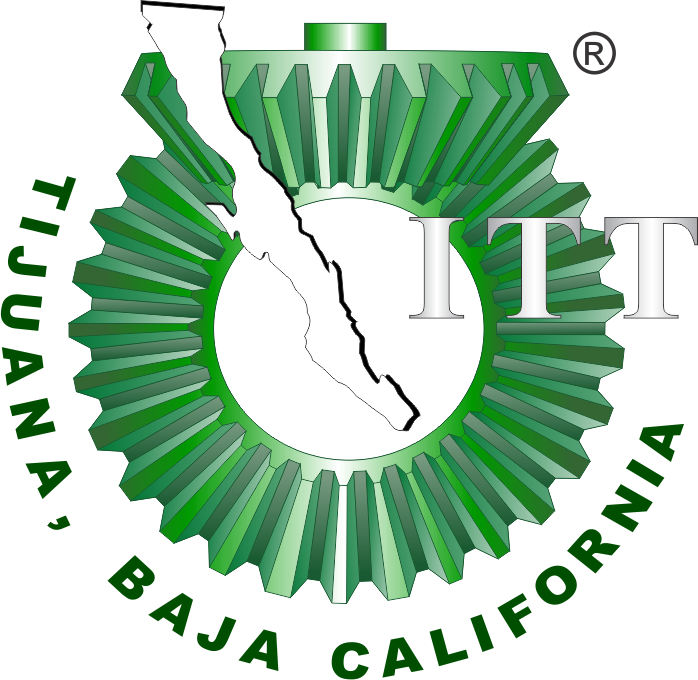

# Práctica 1: Diseño de control para un sistema de segundo orden

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

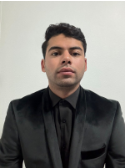

Nombre del alumno: **Perez Chavez Marco Antonio**

Número de control: **19212423**

Correo institucional: **marco.perez193@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Perez19212423';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';
Controlador = 'I';

## Respuesta al escalón

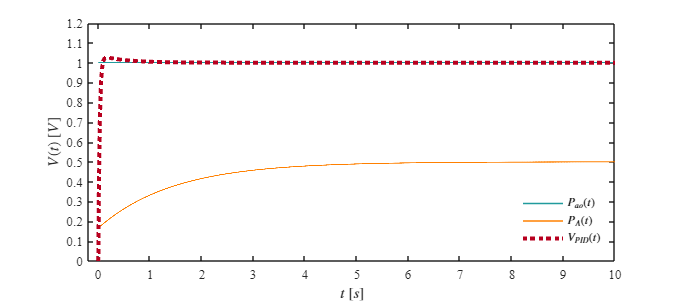

Signal = 'Escalon';
set_param('Perez19212423/SW1','sw','1');
set_param('Perez19212423/SW3','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Ve,x1.Vs,x1.VPID,Signal)

## Respuesta al impulso

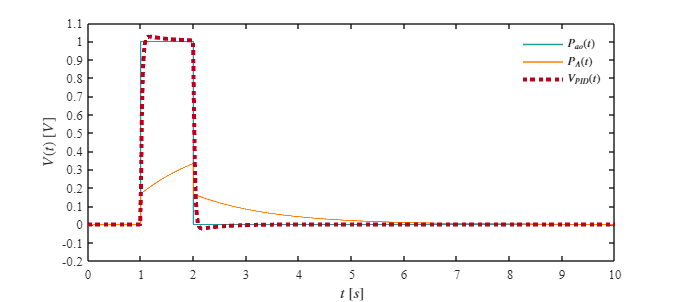

Signal = 'Impulso';
set_param('Perez19212423/SW1','sw','0');
set_param('Perez19212423/SW3','sw','1');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Ve,x2.Vs,x2.VPID,Signal)

## Respuesta a la rampa

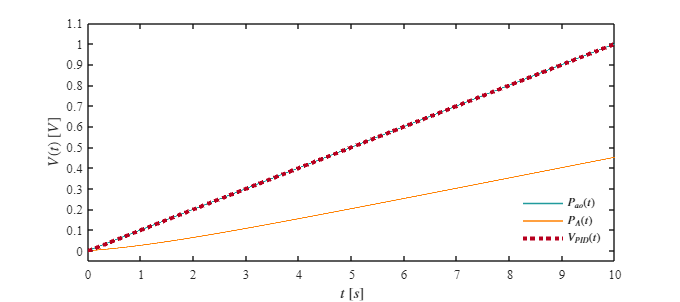

Signal = 'Rampa';
set_param('Perez19212423/SW2','sw','1');
set_param('Perez19212423/SW3','sw','0');
x3 = sim(file,parameters);
plotsignals(x3.t,x3.Ve,x3.Vs,x3.VPID,Signal)

## Respuesta a la función sinusoidal

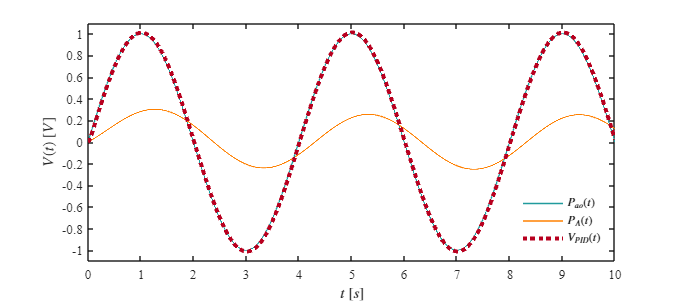

Signal = 'Sinusoidal';
set_param('Perez19212423/SW2','sw','0');
set_param('Perez19212423/SW3','sw','0');
x4 = sim(file,parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.VPID,Signal)

## Función: Respuesta a las señales 

function plotsignals (t,Ve,Vs,VPID,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    %Color 1 naranja [1, 128/255, 0]
    %Color 2 morado [76/255, 31/255, 122/255]
    %Color 3 azul [33/255, 155/255, 157/255]
    %Color 4 rojo [184/255, 0/255, 31/255]
    na1 =  [1, 128/255, 0];
    mor1 = [76/255, 31/255, 122/255];
    azu1 = [33/255, 155/255, 157/255];
    roj1 = [184/255, 0/255, 31/255];
    hold on ; grid off; box on
    
    plot(t,Ve,'LineWidth',1,'Color',azu1)
    plot(t,Vs,'LineWidth',1,'Color',na1)
    plot(t,VPID,':','LineWidth',3,'Color',roj1)
    
    xlabel('$t$ $[s]$','Interpreter','Latex')
    ylabel('$V(t)$ $[V]$','Interpreter','Latex')
    
    L = legend('$P_{ao}(t)$','$P_A(t)$','$V_{PID}(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')
    
    if Signal == "Escalon"
        xlim([-0.2,10]); xticks (0:1:10)
        ylim([0,1.2]); yticks (0:0.1:1.2)
    elseif Signal == "Impulso"
        xlim([0,10]); xticks (0:1:10)
        ylim([-0.2,1.1]); yticks (-0.2:0.1:1.1)
    elseif Signal == "Rampa"
        xlim([0,10]); xticks (0:1:10)
        ylim([-0.05,1.1]); yticks (0:0.1:1.1)
    elseif Signal == "Sinusoidal"
        xlim([0,10]); xticks (0:1:10)
        ylim([-1.1,1.1]); yticks (-1.2:0.2:1.2)
    
end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end